recObj = audiorecorder

recObj =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'



recDuration = 3;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.



play(recObj);

y = getaudiodata(recObj)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


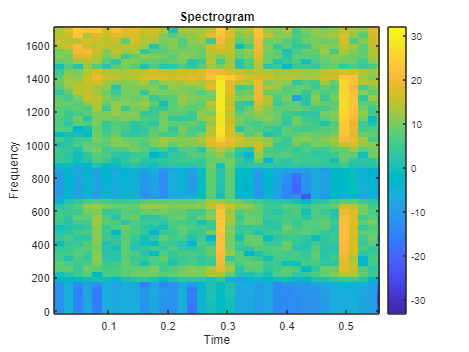


x = fft(y);

% Parameters
fs = 8000; % Sample rate (adjust as per your data)
windowSize = 256; % Window size for spectrogram
overlap = 128; % Overlap between windows

% Apply FFT to compute spectrogram
[S, F, T] = spectrogram(x, windowSize, overlap, windowSize, fs);

% Plot Spectrogram
figure;
imagesc(T, F, 10*log10(abs(S))); % Plot in dB
axis xy;
colorbar;
xlabel('Time');
ylabel('Frequency');
title('Spectrogram');

VI har ikke brug for at se poptoner størrelse så længe det er under 1700 [Hz], hvilket de aldrig vil være.